# Spreading the butter to solve the diffusion equation

We're going to simulate diffusion of N0 molecules, starting in the middle of an *E. coli* cell, using the analytical solution to the diffusion equation provided in Homework 4. First, let's define the model parameters.

N0=100;             %initial number of molecules in the center box
D=0.01;             %diffusion constant in um^2/ms
L=1;                %length of half of the cell in um

The simulation parameters are

dx=0.01;                         %in um
M=(2*L)/dx;                      %number of imaginary boxes in the E. coli cell
TimePoints=[0.01,0.1,1,5,10];    %time points in ms

First, we define the range of values we're going to plot over (x-values) using linspace. 

x=linspace(-L,L,M);

Now we will plot the analytical solution to the differential equation at different points in time. Note that I'm using ".^" to do an element-wise operation instead of raising all of x to the power of two.

%t=0.01ms
c0_1=N0/sqrt(4*pi*D*0.01);
y1=c0_1*exp(-(x.^2)/(4*D*0.01));

%t=0.1ms
c0_2=N0/sqrt(4*pi*D*0.1);
y2=c0_2*exp(-(x.^2)/(4*D*0.1));

%t=1ms
c0_3=N0/sqrt(4*pi*D*1);
y3=c0_3*exp(-(x.^2)/(4*D*1));

%t=5ms
c0_4=N0/sqrt(4*pi*D*5);
y4=c0_4*exp(-(x.^2)/(4*D*5));

%t=10ms
c0_5=N0/sqrt(4*pi*D*10);
y5=c0_5*exp(-(x.^2)/(4*D*10));

Finally, let's plot the distribution at each different time point.

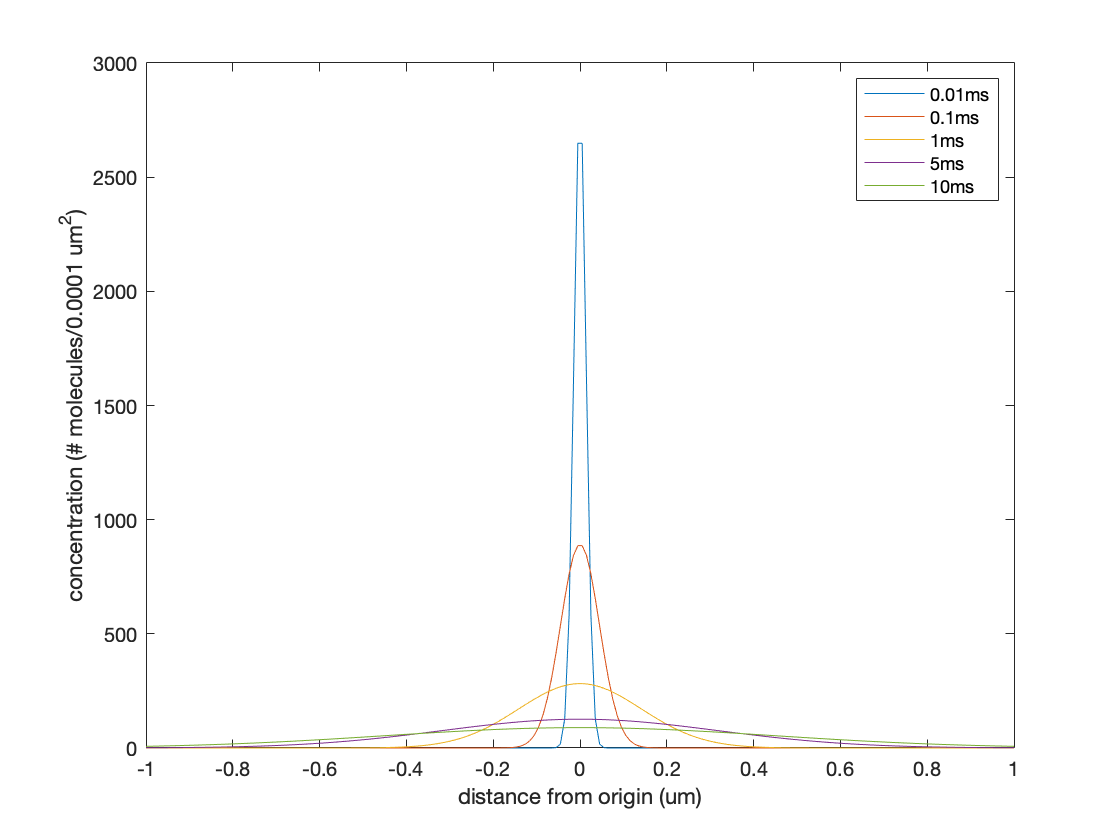

plot(x, y1)
hold on
plot(x, y2)
plot(x, y3)
plot(x, y4)
plot(x, y5)
hold off
xlabel('distance from origin (um)')
ylabel('concentration (# molecules/0.0001 um^2)')
legend('0.01ms', '0.1ms', '1ms', '5ms', '10ms')